# Remaining Useful Life estimation of turbofan (CMAPSS FD00x) using Functional MLP and HybridFL

This example shows how to train a Multi-Layer Perceptron using federated learning. Federated Learning is a technique that enables you to train a network in a distributed, decentralized way. In our case, the Remaining Useful Life of turbofan engines provided by NASA (CMAPSS datasets). Particularly, this example uses the well know FedAvg algorithm for horizontal data partitioning approach.

The input data corresponds to 21 sensors and RUL.

To Run this example, the following tools have to be installed: 

-  Parallel Computing

## Data pre-processing

-  Elbow Point and RC = 130

-  MaxMin Normalization [0,1]

- ( i , Sensor, Engine, Mj)

## Functional Settings

- Subset M4=31

- Training data instances = cycle+Md-1

- Deep Learning Toolbox

## Variables depending the FD00x dataset 

- T= refers to time window size

- FD00x = refers to the dataset name, where x is in [1,2,3,4]

- sensorsCMAPSS= number of features (21 sensors)

-  The percentage of Testing ang Validation data  corresponds to 85% and 15%, respectively.

To Run this example, the following tools have to be installed: 

-  Parallel Computing

- Deep Learning Toolbox

clear;
sensorsCMAPSS=21; % Input sensors
sensorsCMAPSSPerParty=18; % Input sensors
FD00X=4 %

FD00X = 4

Md=31;
percentage=0.85; % Percentage of data from training splits to train the model. The remaining % is used to locally evaluate the learning procedure.
Pr_acceptance=90;

## Set Up Parallel Environment

Create a parallel pool with n workers (n nodes). 

pool = parpool('local',4);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


numWorkers=pool.NumWorkers;

## Load Training  Data

trainingDatastore = parquetread(fullfile(pwd,strcat("train_fd00",num2str(FD00X),".parquet")));
trainingDatastore.setting1=[];
trainingDatastore.setting2=[];
trainingDatastore.setting3=[];
trainingDatastore.x__index_level_0__=[];


statistics= grpstats(trainingDatastore,"id");
statistics.sets=statistics.GroupCount-Md+1;
statistics.end=cumsum(statistics.GroupCount);
statistics.end=statistics.end-Md+1;
statistics.start=statistics.end-statistics.sets+1;
statistics=statistics{:,:};

trainingDatastore=table2array(trainingDatastore(:,3:sensorsCMAPSS+3));

totalEngines=length(statistics);

## Split data by engine id

This is useful to create the data partitioning setting.

Please, pay attention that data partition is performend considering the $\textrm{Jn}$ stratified sampling criterion defined by the ids variable.

IDDs=randperm(totalEngines);

ids={1:numWorkers:totalEngines,1:numWorkers:totalEngines,1:numWorkers:totalEngines,1:numWorkers:totalEngines};
featureType={[5, 9, 15, 13, 18, 12, 20, 4, 8, 10, 14, 17, 19, 11, 3, 1, 16, 2],[16, 3, 2, 4, 14, 9, 15, 12, 7, 18, 20, 13, 10, 5, 17, 6, 19, 8],[9, 19, 16, 20, 10, 15, 2, 17, 6, 7, 1, 5, 11, 8, 18, 3, 4, 12],[5, 2, 9, 16, 8, 15, 6, 1, 4, 13, 12, 10, 11, 18, 17, 7, 14, 19]};
spmd
    % Creating sets
    X_train=[];
    Y_train=[];
    current_set=1;
    localEngines=find(ismember(1:totalEngines,ids{labindex}));
    for trajectory = 1:length(ids{labindex})
        engine = localEngines(trajectory);
        row=statistics(engine,sensorsCMAPSS+7);
        for set = 1:statistics(engine,sensorsCMAPSS+5)
            X_train(current_set,1:sensorsCMAPSSPerParty,:)=transpose(trainingDatastore(row:row+Md-1,featureType{labindex}));
            Y_train(current_set)=trainingDatastore(row,sensorsCMAPSS+1);
            current_set=current_set+1;
            row=row+1;
        end
    end
    
    % Data randomization and creating test and eval datasets
    totalSamples=size(X_train,1);
    
    indexes = 1:totalSamples;
    
    
    XTraining=X_train(indexes(1:ceil(totalSamples*percentage)),:,:);
    YTraining=Y_train(:,indexes(1:ceil(totalSamples*percentage)))';
    indexesEval=indexes(ceil(totalSamples*percentage)+1:totalSamples);
    XValLocal=X_train(indexesEval,:,:);
    YValLocal=Y_train(:,indexes(:,indexesEval))';
end

## Loading evaluating data to evaluate the learning procedure of FedAvg

XVal=[];
YVal=[];
tmpCumulative=0;
for i = 1:1
    tmp = indexesEval{i};
    
    XVal(tmpCumulative+1:tmpCumulative+length(tmp),:,:)=XValLocal{i};
    YVal(tmpCumulative+1:tmpCumulative+length(tmp),:)=YValLocal{i};
    tmpCumulative=tmpCumulative+length(tmp);
end

## Define the Nerwork

% Fix random seed for reproducibility. This variables is altered to generate different initial weights
rng(10);

N1=16;                  % Middle Layer Neurons
N2=8;                   % Middle Layer Neurons
N3=4;                   % Middle Layer Neurons
N4=1;                   % Middle Layer Neurons


B = {};
bk = {};
w2 = {};
b2 = {};
w3 = {};
b3 = {};
w4 = {};
b4 = {};

change1 = {};
changeB1 = {};
change2 = {};
changeB2 = {};
change3 = {};
changeB3 = {};
change4 = {};
changeB4 = {};

SGDWithMomentum=false;


spmd
    
    % Initialization of weights
    B{labindex}=randn(N1,size(featureType{labindex},2));    % Initial weights of input and middle layer connections
    bk{labindex}=randn(N1,1);
    
    w2{labindex}=randn(N2,N1);    % Initial weights of middle and output layer connections
    b2{labindex}=randn(N2,1);
    
    w3{labindex}=randn(N3,N2);    % Initial weights of middle and output layer connections
    b3{labindex}=randn(N3,1);
    
    w4{labindex}=randn(N4,N3);    % Initial weights of middle and output layer connections
    b4{labindex}=randn(N4,1);
    
    % forward
    indexesLocal=1:size(YTraining,1);
    Predictions=1:size(YTraining,1);
    for row=1:size(YTraining,1)
        X=reshape(XTraining(row,:,:),size(featureType{labindex},2),Md)';
        [~,~,~,~,~,~,~,a4,~,~] = forward(X,B{labindex},w2{labindex},w3{labindex},w4{labindex},bk{labindex},b2{labindex},b3{labindex},b4{labindex},Md,Pr_acceptance);
        Predictions(row)=a4;
    end
    % update A
    if labindex == 1
        myData(indexesLocal,labindex)=Predictions;
        iSendDataToNextLab(myData);
    end
    myData = iRecFromPrevLab();
    if labindex ~= 1
        myData(indexesLocal,labindex)=Predictions;
        iSendDataToNextLab(myData);
        if labindex==numWorkers
            fileID = fopen('Predictions.bin','wb');
            fwrite(fileID, myData,'double');
            fclose(fileID);
        end
    end
    
    
    if SGDWithMomentum
        change1{labindex} = 0.0;
        changeB1{labindex} = 0.0;
        change2{labindex} = 0.0;
        changeB2{labindex} = 0.0;
        change3{labindex} = 0.0;
        changeB3{labindex} = 0.0;
        change4{labindex} = 0.0;
        changeB4{labindex} = 0.0;
        
    end
    
end

## Specify Training Options

The model is trained a certain epochs via Stochastic Gradient Descent with momentum. The hyperparamenters involved are the following ones. 

numRounds = 100 ;
numEpochsperRound=10;
miniBatchSize = 1;

Specify the options for SGD optimization. Specify an initial learn rate of 0.01 and momentum 0.9

Specify the options for SGD optimization. Specify an initial learn rate of 0.001.

eta = 0.01;
momentum=0.9;


## Historical data to be exported

ROUND and RMSE_ variables are used to store learning processes.

ROUND=[];
RMSEGLOBAL=[];
RMSE=[];
RMSE2=[];
RMSE3=[];
RMSE4=[];

## Training Models

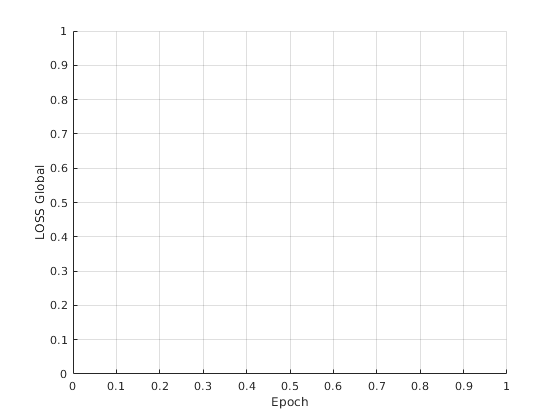

% figure
lineRMSETrain = animatedline('Color',[0.85 0.325 0.098]);
lineRMSETrain2 = animatedline('Color',[0.75 0.425 0.198]);
lineRMSETrain3 = animatedline('Color',[0.65 0.525 0.298]);
lineRMSETrain4 = animatedline('Color',[0.55 0.625 0.398]);
lineRMSETrain5 = animatedline('Color',[0.45 0.725 0.498]);

ylim([0 inf])
xlabel("Epoch")
ylabel("LOSS Global")
grid on

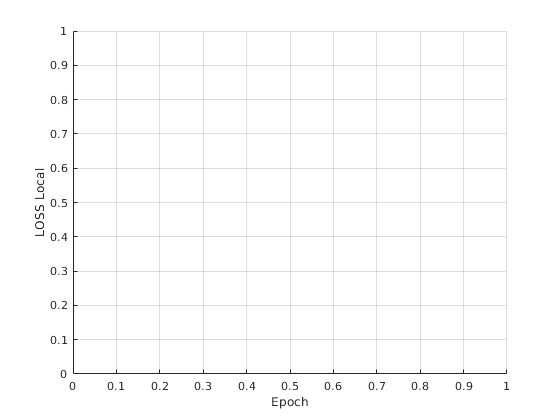


start = tic;

figure
lineRMSELocal = animatedline('Color',[0.85 0.325 0.098]);
ylim([0 inf])
xlabel("Epoch")
ylabel("LOSS Local")
grid on

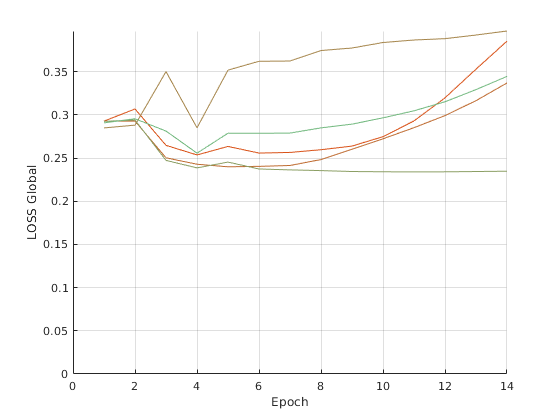

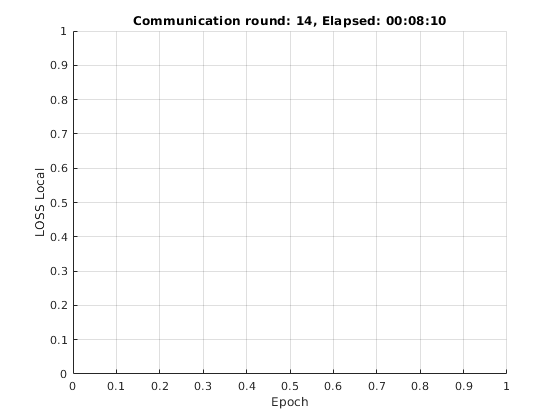

early_stopping=EarlyStopping(10);
for round = 1:numRounds
    spmd
        % forward
        Predictions=1:size(YTraining,1);
        for row=1:size(YTraining,1)
            X=reshape(XTraining(row,:,:),size(featureType{labindex},2),Md)';
            [~,~,~,~,~,~,~,a4,~,~] = forward(X,B{labindex},w2{labindex},w3{labindex},w4{labindex},bk{labindex},b2{labindex},b3{labindex},b4{labindex},Md,Pr_acceptance);
            Predictions(row)=a4;
        end
        
        % update Prediction Matrix
        if labindex == 1
            fileID = fopen('Predictions.bin','r');
            myData = fread(fileID,[size(YTraining,1) numWorkers],'double');
            fclose(fileID);
            myData(indexesLocal,labindex)=Predictions;
            iSendDataToNextLab(myData);
        end
        myData = iRecFromPrevLab();
        if labindex ~= 1
            myData(indexesLocal,labindex)=Predictions;
            iSendDataToNextLab(myData);
            if labindex==numWorkers
                fileID = fopen('Predictions.bin','wb');
                fwrite(fileID, myData,'double');
                fclose(fileID);
            end
        end
        
        for batch=1:fix(size(YTraining,1)/miniBatchSize)
            %Initialize Gradients
            delta1=zeros(N1,size(featureType{labindex},2)); % (4,21)
            db1=0;
            delta2=zeros(N2,N1); % (2,4)
            db2=0;
            delta3=zeros(N3,N2); % (1,2)
            db3=0;
            delta4=zeros(N4,N3); % (1,2)
            db4=0;
            
            for row=1:miniBatchSize
                % Sum of all the local predictions
                X=reshape(XTraining(batch,:,:),size(featureType{labindex},2),Md)';
                Y=YTraining(batch);
                [z1,a1,z2,a2,z3,a3,z4,a4,rho,Pr] = forward(X,B{labindex},w2{labindex},w3{labindex},w4{labindex},bk{labindex},b2{labindex},b3{labindex},b4{labindex},Md,Pr_acceptance);
                rho(:,find(cumsum(Pr)>Pr_acceptance)')=0;
                
                integrationOfPredictions=[];
                workersWithSameLevel=1;
                for s=1:numWorkers
                    if s==labindex
                        integrationOfPredictions=[integrationOfPredictions, a4];
                        
                    else
                        integrationOfPredictions=[integrationOfPredictions, myData(row,s)];
                    end
                end
                
                [z5,a5]=forwardServer(ones(numWorkers,1)/numWorkers,integrationOfPredictions);
                
                d5 = (a5+a4)/2-Y;
                %d5=a4-Y;
                
                
                delta4 = delta4 + d5 * dlogsig(z4,a4)';              %  delta3 = dC/da(L) * da(L)/dz(L)
                db4 = db4 + d5;
                
                d4 = w4{labindex}'*d5.*dlogsig(z3,a3);                         %  d3     = dC/da(L) * da(L-1)/dz(L-1) * w(L)
                
                delta3 = delta3 + d4 *a2';                           %  delta2 = dC/da(L) * da(L-1)/dz(L-1) * w(L) * a(L-1
                db3=db3+d4;
                
                d3 = w3{labindex}'*d4.*dlogsig(z2,a2);                         %  d3     = dC/da(L) * da(L-1)/dz(L-1) * w(L)
                
                delta2 = delta2 + d3 *a1';                           %  delta2 = dC/da(L) * da(L-1)/dz(L-1) * w(L) * a(L-1
                db2=db2+d3;
                
                d2 = w2{labindex}'*d3.*dlogsig(z1,a1);                         %  d2     = dC/da(L) * da(L-1)/dz(L-1) * w(L) * da(L-2)/dz(L-2) * w(L-1)
                
                delta1 = delta1 + d2.*sum(1/Md*(sqrt(Md)*rho*X'),2)';  %  delta1 = dC/da(L) * da(L-1)/dz(L-1) * w(L) * da(L-2)/dz(L-2) * w(L-1) * a(L-2)
                db1=db1+d2;
                
            end
            if SGDWithMomentum
                % Calculate update
                gradient1=1.0/miniBatchSize * delta1;
                gradient2=1.0/miniBatchSize * delta2;
                gradient3=1.0/miniBatchSize * delta3;
                gradient4=1.0/miniBatchSize * delta4;
                gradientB1=1.0/miniBatchSize * db1;
                gradientB2=1.0/miniBatchSize * db2;
                gradientB3=1.0/miniBatchSize * db3;
                gradientB4=1.0/miniBatchSize * db4;
                %Calculate new change
                new_change1 = eta * gradient1 + momentum * change1{labindex};
                new_change2 = eta * gradient2 + momentum * change2{labindex};
                new_change3 = eta * gradient3 + momentum * change3{labindex};
                new_change4 = eta * gradient4 + momentum * change4{labindex};
                new_changeB1 = eta * gradientB1 + momentum * changeB1{labindex};
                new_changeB2 = eta * gradientB2 + momentum * changeB2{labindex};
                new_changeB3 = eta * gradientB3 + momentum * changeB3{labindex};
                new_changeB4 = eta * gradientB4 + momentum * changeB4{labindex};
                % take a step
                B{labindex}  = B{labindex}  - new_change1;
                w2{labindex} = w2{labindex} - new_change2;
                w3{labindex} = w3{labindex} - new_change3;
                w4{labindex} = w4{labindex} - new_change4;
                bk{labindex} = bk{labindex} - new_changeB1;
                b2{labindex} = b2{labindex} - new_changeB2;
                b3{labindex} = b3{labindex} - new_changeB3;
                b4{labindex} = b4{labindex} - new_changeB4;
                % save the change
                change1{labindex} = new_change1;
                change2{labindex} = new_change2;
                change3{labindex} = new_change3;
                change4{labindex} = new_change4;
                changeB1{labindex} = new_changeB1;
                changeB2{labindex} = new_changeB2;
                changeB3{labindex} = new_changeB3;
                changeB4{labindex} = new_changeB4;
            else
                % Update Weights
                B{labindex} = B{labindex} - eta * 1.0/miniBatchSize * delta1; %(100,44)
                bk{labindex} = bk{labindex} - eta * 1.0/miniBatchSize * db1;   %(100,1)
                w2{labindex} = w2{labindex} - eta * 1.0/miniBatchSize * delta2; %(100,100)
                b2{labindex} = b2{labindex} - eta * 1.0/miniBatchSize * db2;    %(100,1)
                w3{labindex} = w3{labindex} - eta * 1.0/miniBatchSize * delta3; %(100,100)
                b3{labindex} = b3{labindex} - eta * 1.0/miniBatchSize * db3;    %(100,1)
                w4{labindex} = w4{labindex} - eta * 1.0/miniBatchSize * delta4; %(100,100)
                b4{labindex} = b4{labindex} - eta * 1.0/miniBatchSize * db4;    %(100,1)
            end
            
        end
        %         [z1,a1,z2,a2] = forward(XVal(featureType{j},:),w1{labindex},w2{labindex},b1{labindex},b2{labindex});
        %
        %         error = sqrt(mse((a2-YVal)));
        %
        %         if labindex == 2
        %             data = [round error round toc(start)];
        %             send(Q,gather(data));
        %         end
        
    end
    
    % Display the training progress of the global model.
    D = duration(0,0,toc(start),'Format','hh:mm:ss');
    % Find normalization factors for each worker based on ratio of data
    % processed on that worker.
    
    PredictionsGlobal=[];
    for j=1:numWorkers
        
        BB=cell2mat(B{j});
        BK=cell2mat(bk{j});
        W2=cell2mat(w2{j});
        B2=cell2mat(b2{j});
        W3=cell2mat(w3{j});
        B3=cell2mat(b3{j});
        W4=cell2mat(w4{j});
        B4=cell2mat(b4{j});
        
        PredictionsVal=[];
        for rowVal=1:size(YVal,1)
            X_Val=XVal(rowVal,:,:);
            X_=reshape(X_Val,size(featureType{j},2),Md)';
            [~,~,~,~,~,~,~,A4,~,~] = forward(X_,BB,W2,W3,W4,BK,B2,B3,B4,Md,Pr_acceptance);
            PredictionsVal(rowVal)=A4;
        end
        PredictionsGlobal=[PredictionsGlobal; PredictionsVal];
        switch j
            case 1
                addpoints(lineRMSETrain,round,sqrt(mse(PredictionsVal-YVal')))
                ROUND=[ROUND;round];
                RMSE=[RMSE;sqrt(mse(PredictionsVal-YVal'))];
            case 2
                addpoints(lineRMSETrain2,round,sqrt(mse(PredictionsVal-YVal')))
                RMSE2=[RMSE2;sqrt(mse(PredictionsVal-YVal'))];
            case 3
                addpoints(lineRMSETrain3,round,sqrt(mse(PredictionsVal-YVal')))
                RMSE3=[RMSE3;sqrt(mse(PredictionsVal-YVal'))];
            case 4
                addpoints(lineRMSETrain4,round,sqrt(mse(PredictionsVal-YVal')))
                RMSE4=[RMSE4;sqrt(mse(PredictionsVal-YVal'))];
        end
        
    end
    error=sqrt(mse(PredictionsGlobal-YVal'));
    RMSEGLOBAL=[RMSEGLOBAL;error];
    addpoints(lineRMSETrain5,round,error)
    
    % Display the training progress of the global model.
    
    title("Communication round: " + round + ", Elapsed: " + string(D))
    drawnow
    
    early_stopping=stop(early_stopping,error);
    
    if early_stopping.early_stop
        break
    end
    
end % loop of epochs

## Load testing data

testingDatastore = parquetread(fullfile(pwd,strcat("test_fd00",num2str(FD00X),".parquet")));
testingDatastore.setting1=[];
testingDatastore.setting2=[];
testingDatastore.setting3=[];
%testingDatastore.s1=[];
%testingDatastore.s5=[];
%testingDatastore.s16=[];
%testingDatastore.s18=[];
%testingDatastore.s19=[];
testingDatastore

testingDatastore = 41214×24 table
    id    cycle       s1          s2           s3          s4         s5          s6           s7           s8           s9         s10         s11          s12          s13         s14         s15      s16      s17         s18      s19       s20          s21       RUL
    __    _____    ________    _________    ________    ________    _______    _________    _________    _________    

## Creating sets

test_statistics= grpstats(testingDatastore,"id");
test_statistics.sets=test_statistics.GroupCount-Md+1;
test_statistics.end=cumsum(test_statistics.GroupCount);
test_statistics.end=test_statistics.end-Md+1;
test_statistics.start=test_statistics.end-test_statistics.sets+1;
test_statisticsByEngine=test_statistics;
test_statistics=test_statistics{:,:};


testingDatastore=table2array(testingDatastore(:,3:sensorsCMAPSS+3));


X_test=[];
Y_test=[];
current_set=1;

for engine = 1:length(test_statistics)
    row=test_statistics(engine,sensorsCMAPSS+7);
    for set = 1:test_statistics(engine,sensorsCMAPSS+5)
        X_test(current_set,1:sensorsCMAPSS,:)=transpose(testingDatastore(row:row+Md-1,1:sensorsCMAPSS));
        Y_test(current_set)=testingDatastore(row,sensorsCMAPSS+1);
        current_set=current_set+1;
        
        row=row+1;
    end
end

## Plot Results by Engine

ENGINE=25;
RC=130;

PredictionsGlobal=[];
for j=1:numWorkers
    Score=0;
    
    
    BB=cell2mat(B{j});
    BK=cell2mat(bk{j});
    W2=cell2mat(w2{j});
    B2=cell2mat(b2{j});
    W3=cell2mat(w3{j});
    B3=cell2mat(b3{j});
    W4=cell2mat(w4{j});
    B4=cell2mat(b4{j});
    
    PredictionsVal=1:size(Y_test,2);
    for rowVal=1:size(Y_test,2)
        Y=Y_test(rowVal);
        X_=reshape(X_test(rowVal,featureType{j},:),size(featureType{j},2),Md)';
        [~,~,~,~,~,~,~,A4,~,~] = forward(X_,BB,W2,W3,W4,BK,B2,B3,B4,Md,Pr_acceptance);
        PredictionsVal(rowVal)=A4;
        if(A4-Y<0)
            score=exp((Y-A4)/13)-1;
        elseif (A4-Y>=0)
            score=exp((A4-Y)/10)-1;
        end
        Score=Score+score;
    end
    PredictionsGlobal=[PredictionsGlobal; PredictionsVal];
    
    MAE=(mae(Y_test*RC-PredictionsVal*RC))
    RMSE=sqrt(mse(Y_test*RC-PredictionsVal*RC))
    Score
end

MAE = 16.3179

RMSE = 19.3881

Score = 356.6320

MAE = 12.5743

RMSE = 17.3706

Score = 285.9131

MAE = 7.9275

RMSE = 17.9179

Score = 199.9313

MAE = 20.4376

RMSE = 21.9617

Score = 435.7988


RC=130;

test_statisticsByEngine.cumSets=cumsum(test_statisticsByEngine.sets);
y=Y_test*RC;
y=vertcat(y,mean(PredictionsGlobal)*RC);
Score=0;
for row=1:size(y,1)
        A4=y(row);
        if(A4-Y_test(row)*RC<0)
            score=exp((Y_test(row)*RC-A4)/13)-1;
        elseif (A4-Y_test(row)*RC>=0)
            score=exp((A4-Y_test(row)*RC)/10)-1;
        end
        Score=Score+score;
end
MAE=(mae(Y_test*RC-mean(PredictionsGlobal)*RC))

MAE = 14.0401

RMSE=sqrt(mse(Y_test*RC-mean(PredictionsGlobal)*RC))

RMSE = 17.5597

Score

Score = 1.1680

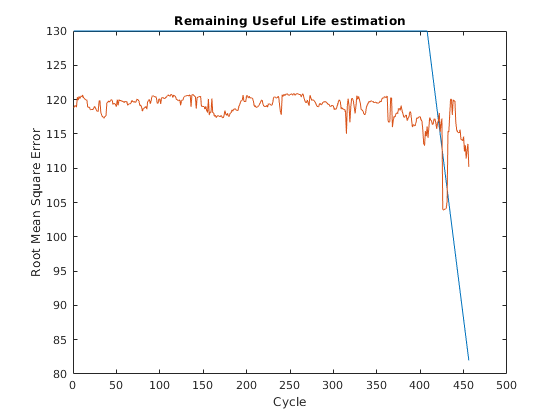

plot(1:test_statisticsByEngine{ENGINE,"end"}-test_statisticsByEngine{ENGINE,"start"}+1,y(:,test_statisticsByEngine{ENGINE,"cumSets"}-test_statisticsByEngine{ENGINE,"sets"}+1:test_statisticsByEngine{ENGINE,"cumSets"}))
title('Remaining Useful Life estimation');
xlabel('Cycle');
ylabel('Root Mean Square Error');
labels = {'Ground Thruth', 'Estimated'};
hold off

## Overall Average Bias and Overall Average Variability

E_m=[];
Std_m=[];
for m=1:size(PredictionsGlobal,1)
    E_m=[E_m; mean(PredictionsGlobal(m,:)-Y_test)];
    Std_m=[Std_m; sqrt(mse(PredictionsGlobal(m,:)-Y_test))];
end
OAB=mean(abs(E_m))

OAB = 0.0519

OAV=mean(Std_m)

OAV = 0.1474

## Reproducibility

d_i_j=0;
for i=1:size(PredictionsGlobal,1)
    for j=(i+1):size(PredictionsGlobal,1)
        d_i_j=d_i_j+(E_m(i)-E_m(j))^2+(Std_m(i)-Std_m(j))^2;
    end
end
d_i_j

d_i_j = 0.0427

## Sending Messages between Workers

function iSendDataToNextLab(mydata)
nextlab = mod(labindex,  numlabs) + 1;
labSend(mydata, nextlab);
end
%--------------------------------------------------------------------------
function result = iRecFromPrevLab()
prevlab = mod(labindex - 2,  numlabs) + 1;
result = labReceive(prevlab);
end

## Local Training and Forward propagation functions

function displayTrainingProgress (data,line)
addpoints(line,double(data(3)),double(data(2)))
D = duration(0,0,data(4),'Format','hh:mm:ss');
title("Epoch: " + data(1) + ", Elapsed: " + string(D))
drawnow
end

function [z1,a1,z2,a2,z3,a3,z4,a4,rho,Pr] = forward(X,B,w2,w3,w4,bk,b2,b3,b4,Md,Pr_acceptance)
[rho,lambda,Pr]=pcacov(X);
rho(:,find(cumsum(Pr)>Pr_acceptance)')=0;
%Functional Layer
z1=sum(1/Md*(B*sqrt(Md)*rho*X'),2)+bk;
a1=logsig(z1);
%Hidden Layer
z2=w2*a1+b2;
a2=logsig(z2);

%Hidden Layer
z3=w3*a2+b3;
a3=logsig(z3);

%Output Layer
z4=w4*a3+b4;
a4=logsig(z4);
end
function [z1,a1] = forwardServer(X,w1)

%Input Layer
z1=w1*X;
a1=z1;
end